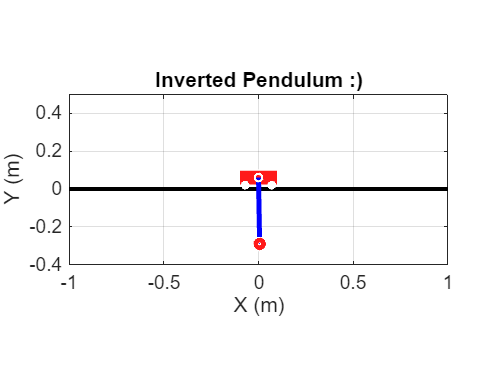

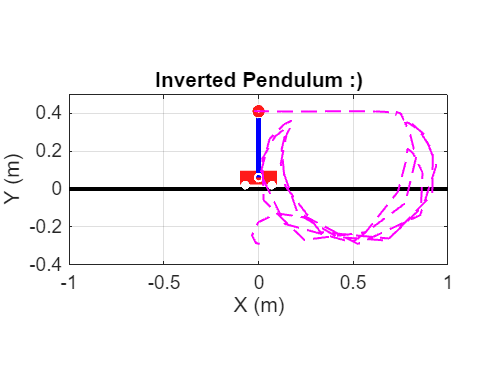

clear; close all; 
clc;

r   = 0.006;       % Radius of motor shaft 
M   = 0.135;       % Mass of cart 
m   = 0.1;         % Mass of pendulum 
I   = 0.0007176;   % Moment of Inertia of Pendulum 
l   = 0.2;         % Center of Mass of Pendulum 
g   = 9.81;        % Gravity 
b   = 0.00007892;  % Viscous damping at pivot of pendulum 
L   = 0.046;       % Motor Inductance 
Rm  = 12.5;        % Motor Resistance 
kb  = 0.031;       % Motor back EMF constant 
kt  = 0.031;       % Motor Torque constant 
c   = 0.63;        % Friction coefficient of cart

Er  = 2 * m * g * l;  % Reference Energy of Pendulum
n   = 3;
k_swing = 1.2;

% LQR Control Design
AA = I * (M + m) + M * m * (l^2);
aa = (((m * l)^2) * g) / AA;
bb = ((I + m * (l^2)) / AA) * (c + (kb * kt) / (Rm * (r^2)));
cc = (b * m * l) / AA;
dd = (m * g * l * (M + m)) / AA;
ee = ((m * l) / AA) * (c + (kb * kt) / (Rm * (r^2)));
ff = ((M + m) * b) / AA;
mm = ((I + m * (l^2)) * kt) / (AA * Rm * r);
nn = (m * l * kt) / (AA * Rm * r);

A  = [0 0 1 0; 0 0 0 1; 0 aa -bb -cc; 0 dd -ee -ff];
B  = [0; 0; mm; nn];

% LQR Gain Calculation
Q = diag([200 1000 0 0]);
R = 0.035;
KK = lqr(A, B, Q, R);

% Simulation Parameters
Ts = 0.01; % Sample time
Tf = 9;    % end time

X0 = [0; 1 * (pi / 180); 0; 0];  % initial state
X_des = [0; pi; 0; 0];           % desired state
u0 = 0;                          % initial control input

% Saturation Function
sat = @(x, x_max, x_min) min(x_max, max(x_min, x));

i = 0;
for k = 0:Ts:Tf
    i = i + 1;
    new_state = RK4_2nd_order(X0, Ts, u0, M, m, g, l, c, b, I);
    
    % Angle normalization
    if new_state(2) < 0
        th = 2 * pi - abs(new_state(2));
    else
        th = new_state(2);
    end
    updated_state = [new_state(1); th; new_state(3); new_state(4)];

    % Data Updating
    Xp(i, :) = updated_state;
    t(i) = k;
    X0 = new_state;

    % Energy Calculation
    theta = new_state(2);
    theta_dot = new_state(4);
    E = m * g * l * (1 - cos(theta)) + 0.5 * (I + m * l^2) * theta_dot^2;

    % Swing-up Control
    accel = 2 * (E - Er) * sign(theta_dot * cos(theta));
    accel = k_swing * g * sat(accel, n * g, -n * g);

    u_swing = (M + m) * accel - m * l * theta_dot^2 * sin(theta) - m * g * l * sin(theta);

    % LQR Control
    u_volt = -KK * (updated_state - X_des);
    u_volt = sat(u_volt, 12, -12);
    u_lqr = volt2force(u_volt, X0(3), kt, kb, Rm, r);

    % Control Switching Logic
    if abs(X_des(2) - updated_state(2)) * (180 / pi) <= 30
        u0 = u_lqr;
    else
        u0 = u_swing;
    end
end

% Animation Plot
figure();
for i = 1:8:length(Xp)
    IP_Animation(Xp(i, 1), Xp(i, 2));
    pause(0.01);
    hold off;
end

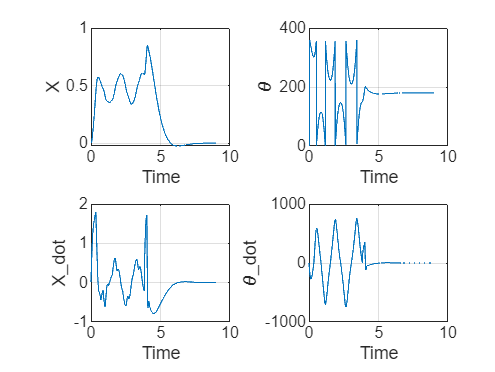


% Plot Results
figure();
subplot(2, 2, 1);
plot(t, Xp(:, 1)); grid on;
ylabel('X'); xlabel('Time');

subplot(2, 2, 2);
plot(t, (180 / pi) .* Xp(:, 2)); grid on;
ylabel('\theta'); xlabel('Time');

subplot(2, 2, 3);
plot(t, Xp(:, 3)); grid on;
ylabel('X\_dot'); xlabel('Time');

subplot(2, 2, 4);
plot(t, (180 / pi) .* Xp(:, 4)); grid on;
ylabel('\theta\_dot'); xlabel('Time');